%BP网络
%通勤方式选择的BP网络（原始数据）
clear                                       %清理内存
P=[18 21 23	23 28 31 36	42 46 48 55	56 58 18 20	25 27 28 30	32 33 33 38	41 45 48 52	56
0 0	0 0	0 0	0 0	0 0	0 0	0 1	1 1	1 1	1 1	1 1	1 1	1 1	1 1
850	1200 850 950 1200 850 1500 1000	950	1200 1800 2100 1800	850	1000 1200 1300 1500	950	1000 1800 1000 1200	1500 1800 1000 1500	1800];
                                            %输入变量
T=[0 0 1 1 1 0 1 1 1 0 1 1 1 0 0 0 0 0 1 0 0 0 0 0 1 0 1 1]; 
                                            %目标输出
net=newff(minmax(P),[1,1],{'logsig','purelin'},'trainlm');

          See help for NEWFF to update calls to the new argument list.
 


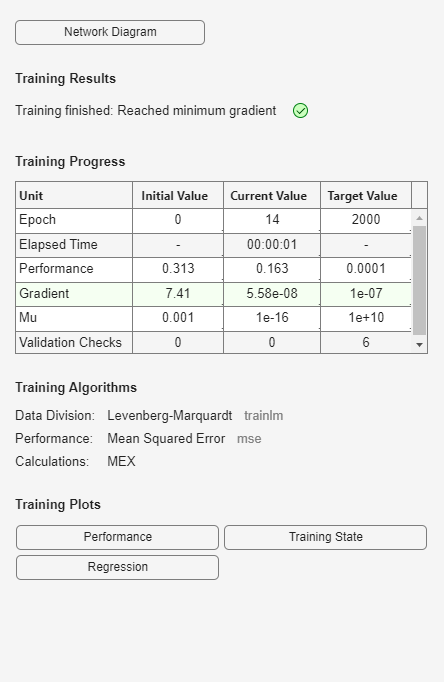

                                            %创建一个隐含层包括2个神经元的BP网络
net.trainParam.epochs=2000;                 %最大学习次数
net.trainParam.goal=0.0001;                 %训练误差0.0001，小于次数可以终止学习
net=train(net,P,T);                         %训练网络

Y=sim(net,P)';Y                             %训练样本的仿真结果

Y =     0.0000
   -0.0000
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500
    0.6500


w1=net.iw{1}                                %输出第一层权数向量

w1 =   -19.0835    2.3456    0.4158


b1=net.b{1}                                 %输出第一层阈值

b1 = 4.1508

w2=net.lw{2}                                %输出第二层权数向量

w2 = -0.6500

b2=net.b{2}                                 %输出第二层阈值

b2 = 0.6500


%BP网络的补充代码
for i=1:length(Y)                           %将仿真结果转换为0-1表示
    if Y(i)>=0.5
        y(i)=1;
    else
        y(i)=0;
    end
end
y                                           %输出预测结果

y =      0     0     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     1     1     0     1     1     1     1     1     1     1


r=1-sum(abs(y-T))/length(Y)                 %计算预测正确率

r = 0.7500